# **2108332 Adjustment Computation**

## **LAB **2 Error and Covariance Propagations

**ชื่อ-นามสกุล: วสุพล คล้ายขำ**

**รหัสประจำตัวนิสิต: 6631137221**

**1.     **ต้องการทราบค่าพิกัด $x_q, y_q$ ของจุด $Q$ ที่เห็นในรูปที่ 1 รวมทั้งต้องการทราบค่าคลาดเคลื่อน $\varepsilon_x, \varepsilon_y$ ของ ค่าพิกัด $x_q, y_q$ที่คำนวณได้โดยใช้จุด $A$ และ $B$ เป็นจุดอ้างอิงค่ามุม $\alpha$ และ $\beta$ เป็นค่ารังวัด มีค่าคลาดเคลื่อนเป็น $\varepsilon_\alpha, \varepsilon_\beta$ ตามลำดับ ส่วนค่าพิกัด $x_A, y_A, x_B, y_B$ ของจุด $A$ และ $B$ เป็นค่าคงที่ ไม่มีความคลาดเคลื่อน

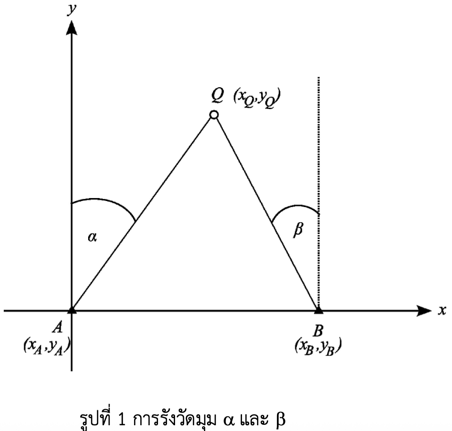

กำหนดให้ $x_A = 0.0\spacem, y_A = 0.0\spacem, x_B = 1000.0\spacem, y_B = 0.0\spacem, \alpha = 1.48765690, \beta = 1.48765409, \varepsilon_\alpha = 0.0001,  \varepsilon_\beta = 0.0001$ 

ให้เขียน MATLAB script เพื่อคำนวณหาค่าพิกัด $x_q, y_q$ และค่าคลาดเคลื่อน $\varepsilon_x, \varepsilon_y$ จากข้อมูลที่กำหนดให้ (ค่ามุมมีหน่วยเป็นเรเดียน)

clear
format long g
syms alpha beta
xA = 0; yA = 0;
xB = 1000; yB = 0;
yq = (tan(beta) * yB + tan(alpha) * yA + xB - xA) / (tan(alpha) + tan(beta));
xq = (tan(alpha) * xB + tan(alpha) * tan(beta) * (yB) + tan(beta) * xA - tan(beta) * tan(alpha) * yA) / (tan(beta) + tan(alpha));
xq_ans = double(subs(xq,{alpha beta},{1.48765690 1.48765409}));
yq_ans = double(subs(yq,{alpha beta},{1.48765690 1.48765409}));
fprintf('(Xq,Yq) คือ (%f , %f)\n', xq_ans, yq_ans);

(Xq,Yq) คือ (500.008489 , 41.666465)


F = [xq;
    yq];
covar_alpha_beta = [0.0001^2,0;
                   0,0.0001^2;];
J = jacobian(F,[alpha,beta]);
J_ans = double(subs(J,[alpha beta],[1.48765690 1.48765409]));
covariance_xy = J_ans * covar_alpha_beta * transpose(J_ans)

covariance_xy =          0.182510420940827     -7.67500697311345e-07
     -7.67500697311345e-07       0.00126742122587497


error_x = sqrt(covariance_xy(1,1))

error_x =          0.427212383880462


error_y = sqrt(covariance_xy(2,2))

error_y =          0.035600859903589


2. กำหนดให้ $X=\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$ เป็นฟังก์ชันของ $U=\left\lbrack \begin{array}{c}
u_1 \\
u_2 \\
u_3 
\end{array}\right\rbrack$ ดังต่อไปนี้


$$x_1 = 5u_1u_2 + u_2^2 + u_3^2$$



$$x_2 = u_1u_3 + u_1^2 - 2u_2$$


โดยที่ covariance matrix ของ 𝑿 คือ


$$\Sigma_{u\;} =\left\lbrack \begin{array}{ccc}
0\ldotp 4 & 0\ldotp 8 & 1\ldotp 7\\
0\ldotp 8 & 1\ldotp 6 & 2\\
1\ldotp 7 & 2 & 3\ldotp 3
\end{array}\right\rbrack$$


ให้เขียน MATLAB script เพื่อคำนวณหา variance-covariance matrix ของ $Y$กำหนดให้ $u_1 = 1, u_2 = 5, u_3 =-3$

syms u1 u2 u3
x1 = 5 * u1 * u2 + u2^2 + u3^2;
x2 = u1*u3 + u1^2 - 2 * u2;
f = [x1;
    x2];
j = jacobian(f,[u1,u2,u3]);
j_ans = subs(j,{u1 u2 u3},{1 5 -3});
covar = [0.4,0.8,1.7;
         0.8,1.6,2;
         1.7,2,3.3];
covar_ans = double(j_ans * covar * j_ans');
disp(covar_ans)

                     458.8                     -23.1
                     -23.1                       1.9

